# Protocol: Designer Pipeline for Studies

Author: Siddhartha Dhiman

Date: January 25, 2019

WIP as of January 29th, 2019

## Abstract

Some text

## Preface:

More text

## I Introduction

Desgner is a preprocessing pipeline that integrates commonly used dMRI preprocessing steps in a specific sequency to enhance SNR and minimize the use of smoothing.

Modifications were made to the original Designer script from NYU to incorporate additional parameterization such as KFA and MKT.

Our approach towards standardizing studies for reproducibility have allowed us to conclude that Designer is the best option with the following options:

This allows Designer to run its standard preprocessing techniques. To contrast with MUSC's pipeline, the table below highlights the preprocessings steps used and their order in both pipelines.

**Designer                                MUSC**

MP-PCA                                 MP-PCA

Gibb's Unringing                    Gibb's Unringing

Rigid body alignment             Rician Correction

EPI + eddy correction            Brain mask

Brain mask                            EPI + Eddy

Smoothing                             Smoothing

Rician Correction

The primary advantages Designer has over MUSC's pipeline are rigid body alignment to aid eddy correction, and placement of Rician correction. In our testing of Rician correction placement, it was discovered that placing Rician correction at the end produced significantly different results than when it is placed after Gibb's unringing. Dr. Veerart's justification on the placement of Rician correction is as such:

`"The rician bias correct using the methods of moments is poorly conditioned and depends on the precise (and accurate) estimation of the expectation value of the Rician distributed signals.  Applying this correction prior to motion and eddy current correction is most likely to be more accurate because signals varies, even within a local window. However, additional interpolation steps tend to smooth the data more, rendering a more precise estimation of the expectation value. At this stage, we consider that the precision gain outweighs the potential drop in accuracy due to the interpolation associated to the motion and EC distortion correction."`

Designer initiates preprocessing with MP-PCA noise estimationan and removal, followed by Gibb's unringing. Then, a 6-DOF rigid body alignmeny is performed to boost the performance of motion correction later on. Rigid body is followed by EPI distortion correction and eddy current correction, which also corrects for motion. A brain mask is then computed, followed by 1.25 FWHM smoothing at 5x5 kernel. This preprocessing pipeline ends with DT/KT estimation and parameterization. 

## 1. Installation

Designer depends on the following software packages to run successfully:

- MATLAB

- Python

- FSL

- Mrtrix3

Failig to meet any of these dependencies will prevent Designer from running. As of January 29, 2019, this pipeline was tested and certified to run on MATLAB 2018b and Python 3.6. Due to MATLAB's current support of only up to Python 3.6, version 3.7 has not been tested.

### 1.1. MATLAB installation

MATLAB is very straightforward to install because it's a packaged installer. Just run the installer, wait for it to finish, then proceed to Python configuration in the next section.

### 1.2 Python Installation

There are several python packages available for installation for all operating systems. It is advisable to use a Conda-based distribution such as Miniconda or Anaconda. This guide is based on Miniconda for Max OS Mojave (v.10.14.3), so same directions apart from directory structures will apply.

#### 1.2.1 Download Miniconda

Miniconda can be downloaded from their official page at [Miniconda Latest Releases](https://conda.io/en/latest/miniconda.html) [https://conda.io/en/latest/miniconda.html]. Download and install the most recent release for your system. Version here doesn't matter as we'll be creating a custom Python 3.6 environment within Conda - yes, the flexibility is beautiful.

#### 1.2.2 Configure Python 3.6 Environment

Upon successful installation of Miniconda, proceed with the following steps:

- Start off by updating conda and then create a new environemnt with a specific version of Python - 3.6 in our case. Name your environment as you please and replace your_env_name with your custom name. We used *py36* to keep things simple.

          2.  Verify the installation of your environment:

            Your output should look something like this:

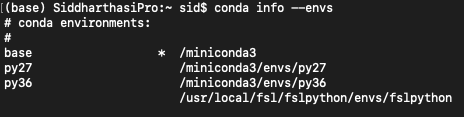

            Our envirnment *py36* appears to have been installed into the environment directory listed on the right. Take note of this directory.

###  1.3. MATLAB-Python Integration

With the successful set up of MATLAB and Python, we need to ensure that the two languages can communicate with each other. Both languages provide tools to establish some form of communication between each other, and this section will guide you throught he step in ensuring that.

#### 1.3.1 Configure Python

It is recommended users configure 

## 2. Directory Configuration

To ensure 

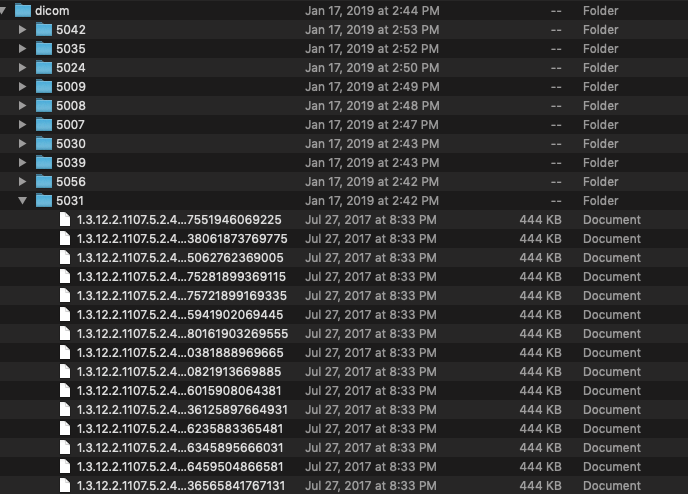

## 3. Clear Memory and Variables

Initiate code by clearning workspace and command-line, good habit. I like to do this on one line.

clc; close all; clear all; warning off;

## 4. Load and Process Directory

### 4.1. Locate Study Directory

Create a folder selection dialogue box to capture directory containing subjects. Every subjects has his or her own unique set of DICOM protcols folders. Then read the subjects in this directory.

studyPath = uigetdir(pwd,'Select subject directory');
studyDir = dir(studyPath);

Any directory the user selects will be assigned to variable *studyDir, *after which a *dir* command reads the contnet if the directory.

#### 4.1.2 Clean up study directory

On some systems such as mac, directories contain hidden folders or files starting with '.' to hold meta-data on folders. Matlab will read these files or folders too so we have to remove them. A *for* loop is us1ed to iterate over all rows of *studyDir* to read the name field. *If *statements are used to check whether there are any '.' files or non-directories. If there are any, an removal index *rmIdx* is marked as a 1, and 0 otherwise. This index is then applied to the list of folders to remove unwanted folders.

for i = 1:length(studyDir)
    rmPattern = [".","..",".DS_Store"];
    %   Check for non-directories
    if studyDir(i).isdir ~= 1
        rmIdx(i) = 1;
        
        %   Check for '.'
    elseif any(contains(studyDir(i).name,rmPattern));
        rmIdx(i) = 1;
        
    else
        %   If nothing found, don't mark for deletion
        rmIdx(i) = 0;
    end
end
studyDir(rmIdx ~= 0) = [];   %   Apply deletion filter

#### 4.1.3 Assign Output

Following the creationa and cleaning of study directory (houses subjects' subfolders), another directory called 'Processing' is created to move relevant dicoms in sorted order. This new folder is created into the parent folder housing the study directory defined by *studyPath*.

A check is performed to determine whether such a directory exists. If it does, it is completely wiped and remade. Otherwise, the directory is simply made.

[fp,~,~] = fileparts(studyPath);
outPath = fullfile(fp,'Processing');
if exist(outPath) == 7;
    rmdir(outPath,'s');
    mkdir(outPath);
else
    mkdir(outPath);
end

### 4.2 Create Subject List

It is usually a good practice to create a vector that contains list of subjects. It is good for automating figure labels, tables etc. Also, it is always advisable to initialize any array if it's expected size is known or could be calculated from stored variables. This makes the program faster and it leaves a smaller memory footprint.

subList = cell(length(studyDir),1);  %   Initialize empty cell
for i = 1:length(studyDir)
    subList{i} = studyDir(i).name;
end
fprintf('Found the following subjects:\n');

Found the following subjects:


disp(subList)

    '20160426_160456_5007'
    '20160428_145905_5009'
    '20160728_151802_5024'
    '20161229_110019_5035'
    '20170114_104623_5039F'
    '20170120_150328_5042'
    '20170202_170757_5030'
    '43719_20170727_183608_5031'
    '43719_20180119_170449_5056_series_01-31'
    '5008'



The *name* field *studyDir* contains the subject names, but it is an inconvenience to acceess because of it's structural nature. So we employ a *for *loop to read it row-by-row and copy it to another cell structure.

## 5 Read DICOM protcols

To automate the designer pipeline, it is impertive to auto-discover commonly occuring protcols across all subjects. The user can then define the protcols that are relevant for a study, which will then be passed on to Designer to process.

There are two ways of doing this depending on whether each subject directory is sorted or not:

- In a sorted directory, folder names of protcols can be read

- In sorted or unsorted directories, *dicomCollection *function can be used to gather details about protcols and select commonly occuring ones

Usually method (2) is slower as Matlab's DICOM reading capability is slower than other DICOM sorting scripts. Hence, method (1) seems the best, where sorting is performed indefinitely to ensure all DICOM images are in relevant protcols folders.

### 5.1 DICOM Sorting

The DICOM files are not sorted in this example, so a sorting algorithm will be employed. Start by reading every .dcm file in a subject folder and determine it's protcols information. Create a new directory based on that protcols information and copy .dcm to new folder.

studyDir = vertcat(dir(fullfile(studyPath,'**/*')),...
    dir(fullfile(studyPath,'**/*.dcm'))); %   Recursive directory listing
rmPattern = {'.','.DS_Store'};   %   Remove files beginning with

%% Clean-up Directory Listing
rmIdx = zeros(1,length(studyDir));
for i = 1:length(studyDir)
    %  Check for directories
    if studyDir(i).isdir == 1
        rmIdx(i) = 1;
        
        %   Check for files starting with'.'
    elseif any(startsWith(studyDir(i).name,'.'));
        rmIdx(i) = 1;
        
    else
        %   If nothing found, don't mark for deletion
        rmIdx(i) = 0;
    end
end
studyDir(rmIdx ~= 0) = [];   %   Apply deletion filter
nFiles = length(studyDir);

parfor i = 1:nFiles
    tmp = dicominfo(fullfile(studyDir(i).folder,studyDir(i).name));
    % Replace all '.' in protocol names with '_'
    tmp.ProtocolName = strrep(tmp.ProtocolName,'.','_');
    sortStatus = fprintf('%d/%d: sorting %s',j,length(studyDir),...
        tmp.ProtocolName);
    subList{i} = tmp.PatientID;
    
    if ~exist(fullfile(outPath,tmp.PatientID,tmp.ProtocolName),'dir')
        mkdir(fullfile(outPath,tmp.PatientID,tmp.ProtocolName));
    else
        ;
    end
    if ~contains(studyDir(i).name,'.dcm')
        newName = [studyDir(i).name '.dcm'];
    else
        newName = studyDir(i).name;
    end
    copyfile(tmp.Filename,fullfile(outPath,tmp.PatientID,...
        tmp.ProtocolName,newName));
    
    %fprintf('Sorting %s: %d/%d',tmp.PatientID,i,nFiles);
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 8 workers.
0/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DKI_B00/53440: sorting DIFF_siemens_dir_2_7_AVE20/53440: sorting DIFF_siemens_dir_2_7_AVE20/53440: sorting DIFF_siemens_dir_2_7_AVE20/53440: sorting DIFF_siemens_dir_2_7_AVE20/53440: sorting DIFF_siemens_dir_2_7_AVE20/53440: sorting DIFF_siemens_dir_2_7_AVE20/53440: sorting DIFF_siemens_dir_2_7_AVE20/53440: sorting DIFF_siemens_dir_2_7_AVE20/53440: sorting DIFF_siemens_dir_2_7_AVE20/53440: sorting DIFF_siemens_dir_2_7_AVE20/53440: sorting DIFF_siemens_dir_2_7_AVE20/53440: sorting DIFF_siemens_dir_2_7_AVE20/53440: sorting D

subList = unique(subList);


### 5.2 Create Subject List from Output

subList = dir(outPath);
rmPattern = [".","..",".DS_Store"];
for i  =1:length(subList)
    %   Check for non-directories
    if subList(i).isdir ~= 1
        rmIdx(i) = 1;
        
        %   Check for '.'
    elseif any(contains(subList(i).name,rmPattern));
        rmIdx(i) = 1;
        
    else
        %   If nothing found, don't mark for deletion
        rmIdx(i) = 0;
    end
end
subList(rmIdx ~= 0) = [];   %   Apply deletion filter
subList = {subList(:).name};

### 5.2 Unique Protocols List

Next, information on each imaging protocols is required to instruct Designer which folder to look into. This can be achieved by quering each sorted DICOM directory, concatenating the list of all protcols found and finding unique protcols.

seriesNames = dir(fullfile(outPath,subList{1}));
for i = 2:length(subList)
    tmp = dir(fullfile(outPath,subList{i}));
    seriesNames = vertcat(seriesNames,tmp);

Found the following commonly occuring imaging protocols:


end
for i = 1:length(seriesNames)

    'DIFF_siemens_dir_2_7_AVE1'    'DIFF_siemens_dir_2_7_AVE2'    'DKI_B0'



    seriesList{i} = seriesNames(i).name;
end

%   Clean up to remove '.' and '..'
seriesList(strcmp(seriesList(:),'.')) = [];
seriesList(strcmp(seriesList(:),'..')) = [];

%   Create unique list and count occurence
[seriesUniList,~,seriesUniIdx] = unique(seriesList);
seriesUniCnt = histc(seriesUniIdx,1:numel(seriesUniList));


    'DIFF_siemens_dir_2_7_AVE1'    'DIFF_siemens_dir_2_7_AVE2'    'DKI_B0'



%   Locate unique protcols which have the same numer of occurences as number
%   of subjects
cmnSeriesIdx = find(seriesUniCnt == numel(subList));

%   Refine unique list down to protcols which only exists in all subjects
fprintf('Found the following commonly occuring imaging protocols:\n');
seriesUniList = seriesUniList(cmnSeriesIdx);
disp(seriesUniList);

The variable *seriesUniList *holds unique protcols that appear throughout all subject folders. This implies that these protcols or folder names will appear in every subject so the researcher can easily select one or multiple of them to work on.

### 5.3 Generate UI Box to Select Relevant Protcols

The generation of a unique protcols list allows one to produce a UI box that presents all detected unique protcols as selectable options. Depending on the protcols selected, this script will parse that information to Designer. A multi-selection box is ideal here to select more than one protcols, should multiple averaging runs be present in an  imaging pipeline.

[seriesIdx seriesSel] = listdlg('PromptString','Select relevant sequences:',...
    'SelectionMode','multiple',...
    'OKString','Run Designer',...
    'CancelString','Cancel',...
    'ListSize',[300 500],...
    'ListString',seriesUniList);
disp(seriesUniList(seriesIdx));

Successful completion of the dialogue box will produce two variables - *seriesIdx* and *seriesSel, *which hold the index of selected choices in *seriesUniList *and whether or not the user made a selection or not. Using these variables, we can control whether to terminate the script or proceed with Designer processing.

## 6 Run Designer

With DICOMs sorted and relevant protcols selected, Designer can be easily called per subject to process all relevant files and place the output in relevant folders.

### 6.1 Create Designer Directory

Create a new directory alongside 'Processing' for Designer output - call it 'Output'. This output directory houses subject subdirectories with all Designer outputs.

desPath = fullfile(fp,'Output');
mkdir(desPath);
for i = 1:length(subList)
    mkdir(fullfile(desPath,subList{i}));
end

### 6.2 Run Designer

With all diredctories in place, it is now simple to run designer, which requires the following syntax to run:

In case of more than one protcols, this can be run as:

#### 6.2.1 Create Repeated String Spec

In this example, the there are a total of three relevant protcols: AVG1,AVG2 and B0s, which need to be parsed into Designer appropriately. This section ensures that this input is generated correctly. Inputs can be concatenated and expressed via *sprintf.*

repInput = repmat('%s,',1,numel(seriesIdx));
% Remove the comma at end
repInput = repInput(1:end-1);

This code repeats a string spec (%s) a number of times defined by the number of protcols selected. The comma at the end is removed by selecting all characters appearing in that string except the one in the end (end - 1).

#### 6.2.2 Create Designer Input and Output Strings

Now that a string format has been automated to repeat as many times as the number of selected protcols, they can easily be replaces by an actual directory using *sprintf*.

for i = 1:length(subList)
    for j = 1:length(seriesIdx)
        seriesUniPath(j) = fullfile(outPath,subList{i},seriesUniList(seriesIdx(j)));
    end
    desInput = sprintf(repInput,seriesUniPath{:});
    desOutput = sprintf(fullfile(desPath,subList{i}));
    
    runDesigner = sprintf('./designer.sh %s %s',...
        desInput,desOutput);
%     runDesigner = sprintf('python designer.py -denoise -extent 5,5,5 -degibbs -rician -mask -prealign -smooth 1.25 -eddy -rpe_header -DKIparams -DTIparams %s $s',...

/bin/bash: activate: No such file or directory
/bin/bash: activate: No such file or directory
/bin/bash: activate: No such file or directory
/bin/bash: activate: No such file or directory
/bin/bash: activate: No such file or directory
/bin/bash: activate: No such file or directory
/bin/bash: activate: No such file or directory
/bin/bash: activate: No such file or directory
/bin/bash: activate: No such file or directory
/bin/bash: activate: No such file or directory


%         desInput,desOutput);
    system(runDesigner,'-echo');
end